# CODEC JPEG

## Description

The objective of this live script is to perform the compression of a JPEG image and compare its performance with the JPEG compression that Matlab implements (`imwrite())`. 

An image is selected and compressed for different values of the compression quality parameter and different metrics are evaluated: SSIM, MSE, the size of the compressed image in bits/pixel and the speed of encoding and decoding.

## Initialization and configuration

clc;
clear variables;
close all;

% Sets default font and size for figures
defaultFontName = 'Verdana';
defaultFontSize  = 11;
set(groot, 'DefaultAxesFontName', defaultFontName);
set(groot, 'DefaultAxesFontSize', defaultFontSize - 2);
set(groot, 'defaultFigureUnits', 'centimeters', 'defaultFigurePosition', [0 0 16 10]);

% The following lines require Matlab R2021a
v = version('-release'); 
if (str2double(v(1:4)) >= 2021)
    s = settings;
    s.matlab.fonts.editor.normal.Size.PersonalValue = defaultFontSize;
    s.matlab.fonts.editor.normal.Name.PersonalValue = defaultFontName;
end

Compressed JPEG image quality values (between 1 and 100).

quality = 10:10:90;
forceGrayscale = false;

Image to compress.

imgOriginalFilename = 'images/peppers.png';
imgOriginal = imread(imgOriginalFilename);

Convert the image to grayscale if you want to test in this mode.

if (forceGrayscale)
    imgOriginal = rgb2gray(imgOriginal);
end

Make sure that the dimensions of the image are integer multiples of 8.

imgOriginal = resizeImageTo8(imgOriginal);

Temporary file for the Matlab JPEG compressor.

imgCompressedFilename = strcat(tempname, '.jpg');

## Simulation for the different quality values

Vectors where the results will be saved.

mseValues = zeros(size(quality));
ssimValues = zeros(size(quality));
codedImageRates = zeros(size(quality));
codingTimes = zeros(size(quality));
decodingTimes = zeros(size(quality));

mseValuesMatlab = zeros(size(quality));
ssimValuesMatlab = zeros(size(quality));
codedImageRatesMatlab = zeros(size(quality));
codingTimesMatlab = zeros(size(quality));
decodingTimesMatlab = zeros(size(quality));

Compute metric values.

for nn = 1:numel(quality)
    fprintf('----------------------- quality = %d   -------------------------\n', quality(nn));
    
    % JPEG coding
    tic;
    [bitStr, imgDimensions] = jpegEncoder(imgOriginal, quality(nn));
    t = toc * 1e3;
    codingTimes(nn) = t;

    % JPEG decoding
    tic;
    imgRestored = jpegDecoder(bitStr, imgDimensions, quality(nn));
    t = toc * 1e3;
    decodingTimes(nn) = t;

    % Matlab's JPEG coding
    tic;
    imwrite(imgOriginal, imgCompressedFilename, 'jpeg', 'Quality', quality(nn));
    t = toc * 1e3;
    codingTimesMatlab(nn) = t;
    
    % Matlab's JPEG decoding
    tic;
    imgRestoredMatlab = imread(imgCompressedFilename);
    t = toc * 1e3;
    decodingTimesMatlab(nn) = t;
    
    % Compute metric values
    mseValues(nn) = immse(imgOriginal, imgRestored);
    mseValuesMatlab(nn) = immse(imgOriginal, imgRestoredMatlab);
    
    ssimValues(nn) = ssim(imgOriginal, imgRestored);
    ssimValuesMatlab(nn) = ssim(imgOriginal, imgRestoredMatlab);
    
    imgInfo = imfinfo(imgCompressedFilename);
    codedImageRates(nn) = jpegCodedImageSize(bitStr, imgDimensions);
    codedImageRatesMatlab(nn) = 8 * imgInfo.FileSize / (imgInfo.Height * imgInfo.Width);

    % Prints some values
    fprintf('              MSE = %2.3f\n', mseValues(nn));
    fprintf('             SSIM = %2.3f\n', ssimValues(nn));
    fprintf(' Compressed image = %2.2f bit/pixel\n', codedImageRates(nn));
end

----------------------- quality = 10   -------------------------


              MSE = 81.145


             SSIM = 0.953


 Compressed image = 0.42 bit/pixel


----------------------- quality = 20   -------------------------


              MSE = 42.137


             SSIM = 0.973


 Compressed image = 0.55 bit/pixel


----------------------- quality = 30   -------------------------


              MSE = 29.510


             SSIM = 0.980


 Compressed image = 0.67 bit/pixel


----------------------- quality = 40   -------------------------


              MSE = 23.584


             SSIM = 0.984


 Compressed image = 0.77 bit/pixel


----------------------- quality = 50   -------------------------


              MSE = 19.805


             SSIM = 0.987


 Compressed image = 0.88 bit/pixel


----------------------- quality = 60   -------------------------


              MSE = 16.942


             SSIM = 0.988


 Compressed image = 0.99 bit/pixel


----------------------- quality = 70   -------------------------


              MSE = 13.963


             SSIM = 0.990


 Compressed image = 1.17 bit/pixel


----------------------- quality = 80   -------------------------


              MSE = 10.737


             SSIM = 0.992


 Compressed image = 1.48 bit/pixel


----------------------- quality = 90   -------------------------


              MSE = 6.648


             SSIM = 0.994


 Compressed image = 2.29 bit/pixel


## Graphic comparison

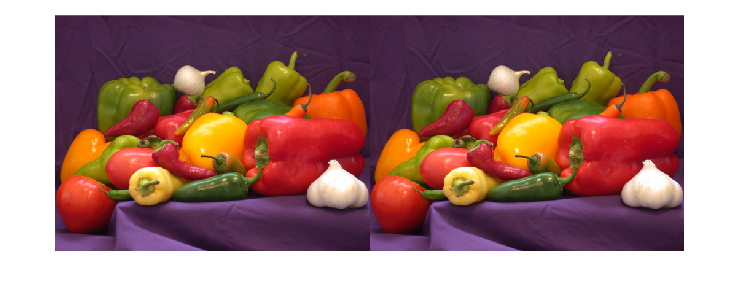

montage({imgOriginal, imgRestored});

## Graphs with the results

**SSIM**

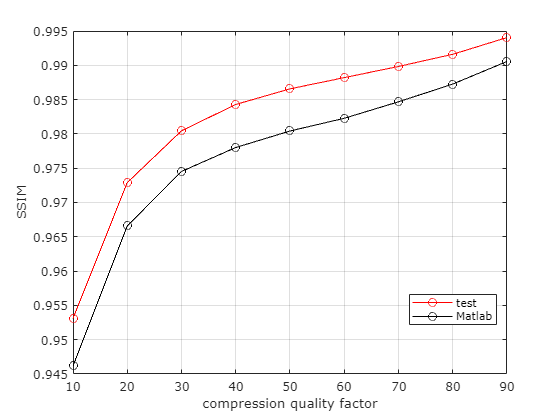

figure(10);
plot(quality, ssimValues, 'r-o');
hold on;
plot(quality, ssimValuesMatlab, 'k-o');
hold off;
legend('test', 'Matlab', 'Location', 'best');
grid on;
ylabel('SSIM');
xlabel('compression quality factor');

**Comments**:

The upper graph shows a slight improvement in terms of SSIM (of hundredths or thousandths) against the implementation provided by Matlab for any of the quality factors tested. Therefore, in terms of SSIM, the visual results of both implementations are practically the same.

**MSE**

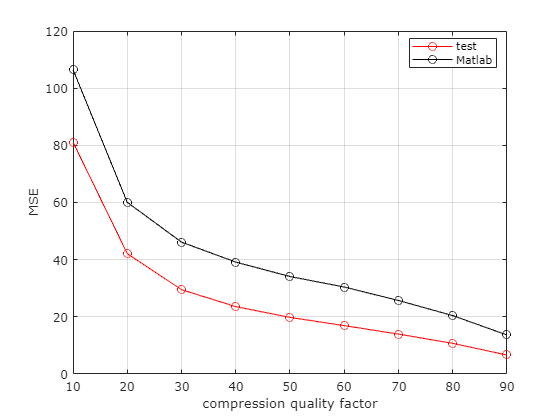

figure(20);
plot(quality, mseValues, 'r-o');
hold on;
plot(quality, mseValuesMatlab, 'k-o');
hold off;
legend('test', 'Matlab', 'Location', 'best');
grid on;
ylabel('MSE');
xlabel('compression quality factor');

**Comments**:

With the results obtained for MSE, a broader improvement can be observed for any of the quality factors tested (especially for those with a lower quality factor). However, MSE is a metric that works by comparing the values of two images at exactly the same positions. Therefore, the higher the compression applied, the worse the results it returns. Although the image may still be recognizable and indistinguishable to the human eye. The case of SSIM is local because it isn't exactly point-to-point (as is the case of MSE), although it does have a locality of fixed size.

**Compression rate in bit/pixel**

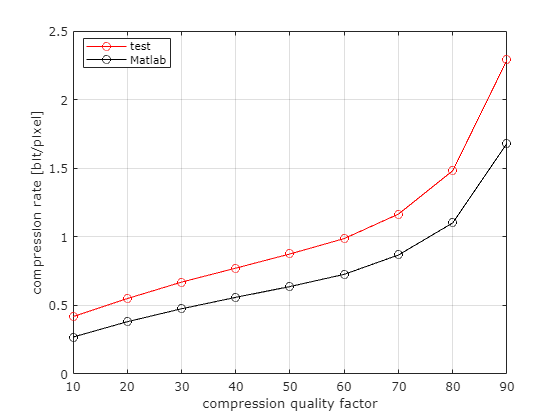

figure(30);
plot(quality, codedImageRates, 'r-o');
hold on;
plot(quality, codedImageRatesMatlab, 'k-o');
hold off;
legend('test', 'Matlab', 'Location', 'best');
grid on;
ylabel('compression rate [bit/pixel]');
xlabel('compression quality factor');

**Comments**:

In terms of compression, the Matlab implementation shows better results in any of the quality factors applied, although not far from those obtained with the tested implementation. This is because Matlab applies chrominance decimation in its implementation, which is a type of lossy compression. Said decimation implies a greater compression even in the 4:2:2 case, since a good portion of the chrominance data is discarded. This has two consequences: the compression rate is improved at the cost of worsening the quality metrics (SSIM and MSE).

**Encoding time**

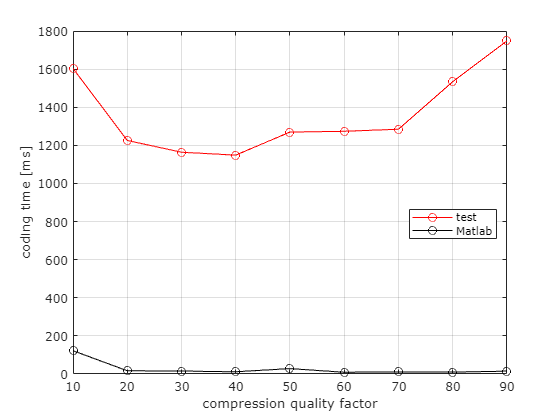

figure(40);
plot(quality, codingTimes, 'r-o');
hold on;
plot(quality, codingTimesMatlab, 'k-o');
hold off;
legend('test', 'Matlab', 'Location', 'best');
grid on;
ylabel('coding time [ms]');
xlabel('compression quality factor');

**Comments**:

The compression time is something that depends on the specifications of the computer on which it's performed, as well as the operations that may be running in the background at that time. However, and despite all these details, it can be seen how the Matlab implementation is faster in this task. This is also due to the way chosen to implement said algorithm (using a cell array).

**Decoding time**

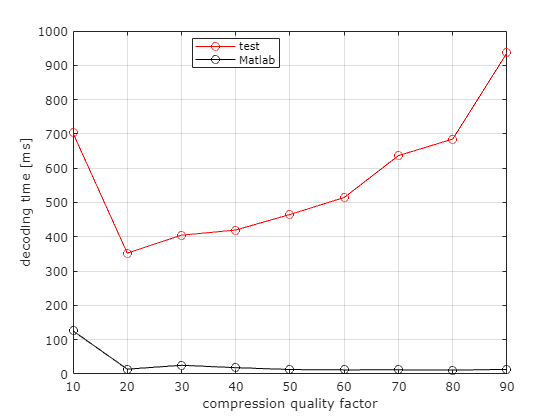

figure(50);
plot(quality, decodingTimes, 'r-o');
hold on;
plot(quality, decodingTimesMatlab, 'k-o');
hold off;
legend('test', 'Matlab', 'Location', 'best');
grid on;
ylabel('decoding time [ms]');
xlabel('compression quality factor');

**Comments**:

In the case of decoding times, the same thing happens as what was mentioned for encoding times, and for the same reasons. It's also for this reason that this implementation doesn't exceed the almost instantaneous times (less than 100 milliseconds) that it takes to perform the Matlab implementation.